# **LABORATORIO 1 ROBOTICA**

**UNIVERSIDAD NACIONAL DE COLOMBIA**

**Aristides Daniel Cantero Castillo**

**Farid Alexis Estepa Quintero **

**William Andrés Castillo Bautista**

**a) Figura robot**

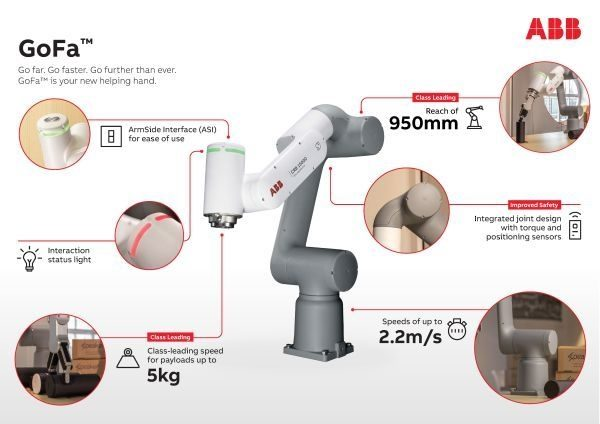

**b) Capacidad de carga.**

Tal como lo muestra la figura y revisando las especificaciones en el catálogo, la capacidad de carga (payload) de este robot es de 5kg. Hay que tener en cuenta que a la hora de agregar el efector final, el payload se reduce.

**c) Alcance vertical y horizontal. **

**d) Repetibilidad. **

**e) Gráfica(s) de espacio alcanzable.**

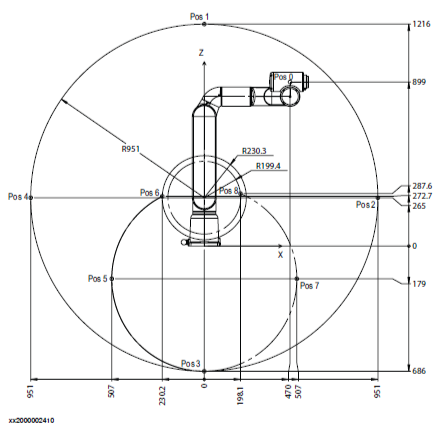

Para encontrar las zonas del espacio de trabajo del robot (en el plano XZ) , se configura el robot en 8 posiciones diferentes y se trazan las zonas, dichas posiciones están declaradas en la siguiente tabla:

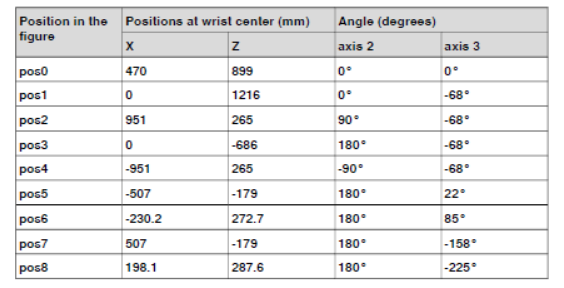

Para encontrar las zonas del espacio de trabajo del robot (en el plano XY), se configura el robot en las posiciones extremas y se trazan las zonas, dichas posiciones están declaradas en la siguiente tabla:

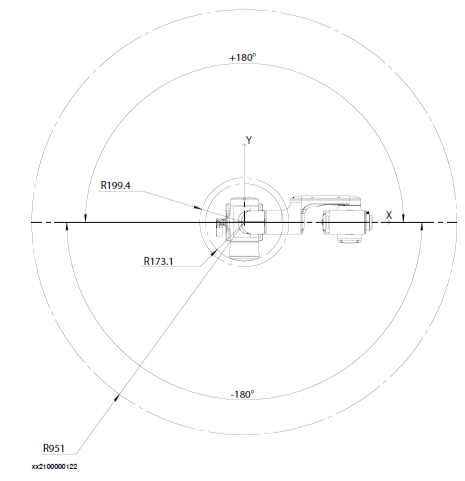

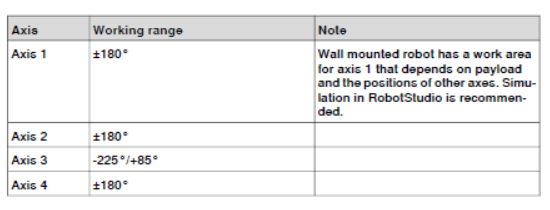

** f ) Tabla de parámetros DH.**

** g) Qué software utiliza el fabricante para diseño de celdas o programación. **

**h) ¿Qué otras características tiene? (Grado de protección IP, colaborativo, normas de seguridad etc.) **

**i) Haga un análisis del diagrama de la capacidad de carga.**

En la imagen a continuación, se puede observar el diagrama de carga para el efector final en posición vertical (muñeca vertical) hacia arriba, en donde ‘L’ equivale a la distancia en metros entre el centro de masa de la carga y efector final en el  plano XY y ‘Z’ equivale a la distancia en metros entre el centro de masa de la carga y el efector final en el eje Z. ‘L’ es igual a $L=\sqrt{X^2 +Y^2 }$, siendo ‘X’ el desplazamiento en el eje X y ‘Y’ el desplazamiento en el eje Y.

Teniendo en cuenta esas longitudes, se puede conocer mediante el diagrama la carga que se puede aplicar sobre la muñeca, verificando que esté dentro de la región de dicha carga.

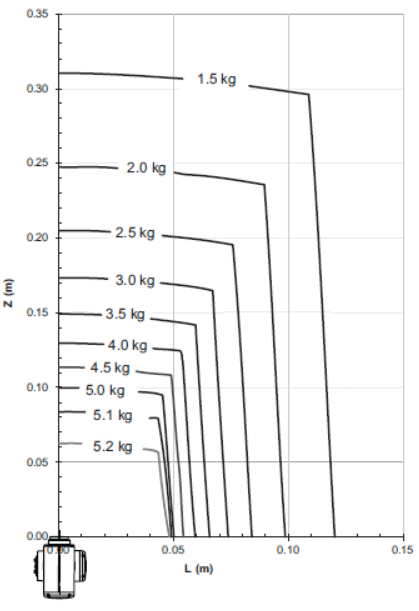

En la imagen a continuación, se puede observar el diagrama de carga para el efector final en posición vertical (muñeca vertical) hacia abajo, en donde ‘L’ equivale a la distancia en metros entre el centro de masa de la carga y efector final en el  plano XY y ‘Z’ equivale a la distancia en metros entre el centro de masa de la carga y el efector final en el eje Z. ‘L’ es igual a $L=\sqrt{X^2 +Y^2 }$, siendo ‘X’ el desplazamiento en el eje X y ‘Y’ el desplazamiento en el eje Y.

Teniendo en cuenta esas longitudes, se puede conocer mediante el diagrama la carga que se puede aplicar sobre la muñeca, verificando que esté dentro de la región de dicha carga.

Se puede deducir que se tiene una mayor capacidad de carga para la posición de la muñeca apuntando hacia abajo.

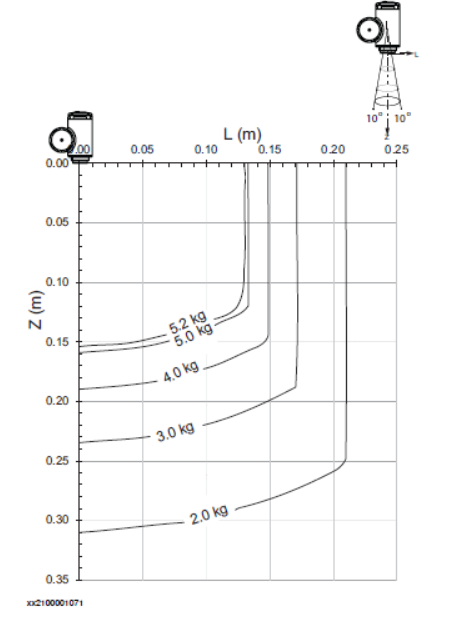

## 6. Modelo Geométrico Directo

clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;

L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);


plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[130 20]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);
figure;
hold on;
Robot_ABB.fkine([0 0 0 0 0 0]); 
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 0 1.5]);
Robot_ABB.teach([0 0 0 0 0 0]);
%Robot_ABB.teach([0 0 -pi/2 0 0 0]);
%Robot_ABB.teach([0 pi/2 -pi/2 0 -pi/2 0]);
